# **Exercise n°3**

clc
clear

Parameters:

alpha = 8;

t = 0:0.01/(4*pi/(alpha+1)):4*pi/(alpha+1);

Choose the option:

choice = true; %r = 1 if false, r = 2 if true

if choice == false
    r = 1
else
    r = 2e1
end

r = 20

 Bernoulli’s leminscate desired trajectory:

x_d = r.*cos((alpha+1).*t)./(1+(sin((alpha+1).*t).^2));
y_d = r.*cos((alpha+1).*t).*sin((alpha+1)*t)./(1+(sin((alpha+1).*t).^2));

Computation of the random initial position within 0.5 m from the desired initial one:

d = 0.5; % meters

x_i = x_d(1,1) + d*rand

x_i = 20.4074

y_i = y_d(1,1) + sqrt(d^2-(x_i-x_d(1,1))^2)*rand

y_i = 0.2626

d_p = sqrt((x_d(1,1)-x_i)^2+(y_d(1,1)-y_i)^2) % distance from the desired point

d_p = 0.4847

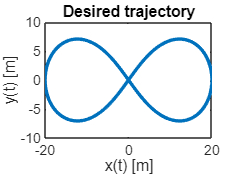


plot(x_d,y_d,'LineWidth',2)
title('Desired trajectory')
xlabel('x(t) [m]')
ylabel('y(t) [m]')

Parameters for **linear control**:

zeta = 0.7;

% constant gains
k_1 = 500;
k_3 = k_1;

Parameters for **(almost) nonlinear control**:

% constant gain
k_2 = 500; %buono valore 500, 750 e 1000


Open **Simulink model** of linear control and (almost) nonlinear control:

if zeta > 0 && zeta < 1 && k_1 > 0 && k_3 > 0
    open("Exercise_3_Simulink.slx")
elseif zeta <= 0 || zeta >= 1
    disp('Value of damping not valid!')
elseif k_1 <= 0 || k_3 <= 0
    disp('Value of gains for linear control not valid!')
elseif k_2 <= 0
    disp('Value of gains for (almost) nonlinear control not valid!')
end